## IE311 - Aula Prática 2

## Simulador SAR

**Recapitulação da Aula Prática 1**

A aeronave voa em linha reta, a 180 m acima do solo e com velocidade constante de 100 km/h. O eixo x indica a direção de voo; o eixo y, a direção ortogonal à direção de voo, à direita; e o eixo z, a direção vertical, apontando para o centro da terra. A trajetória da aeronave se inicia em (0, 0, -180) m e termina em (500, 0, -180) m. Há dois alvos pontuais no solo:

- R1 na posição (230, Rgmin + 2*Lf/5, 0) com taxa de reflexão igual a 50;

- R2 na posição (270, Rgmin + 3*Lf/5, 0) com taxa de reflexão igual a 100.

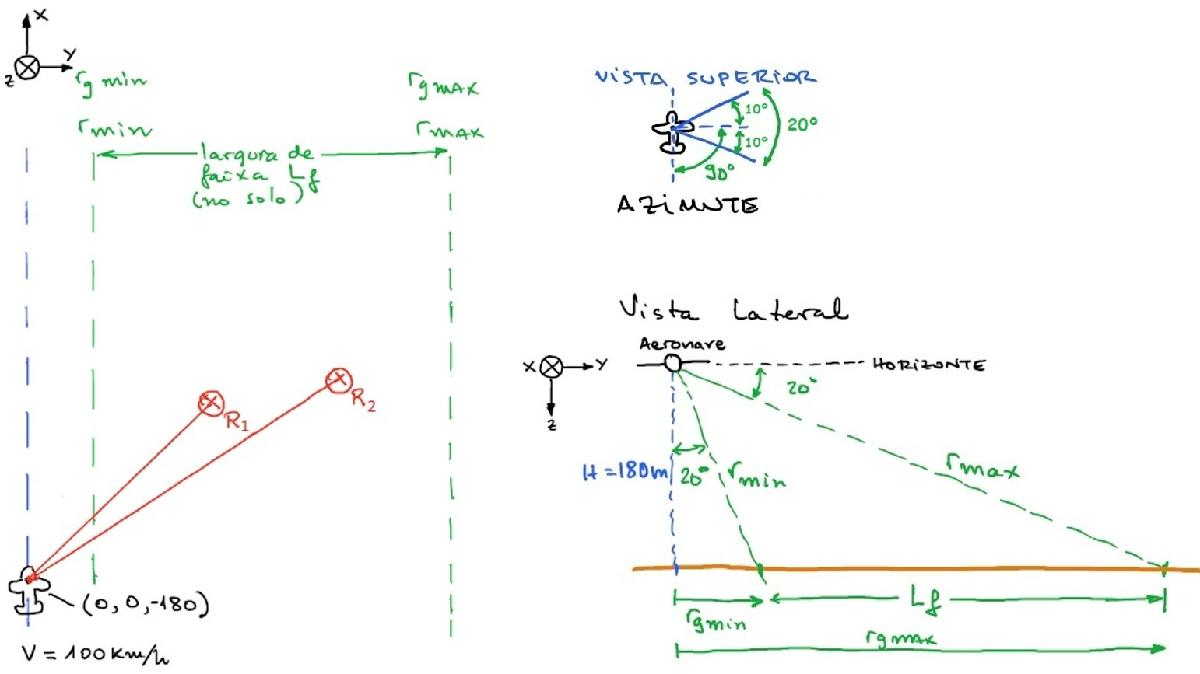

A antena do radar tem uma abertura em azimute de 20 graus e centrada na linha ortogonal à direção de voo. Verifique que, quando o radar se encontra na posição (300, 0, -180) m, apenas o alvo R2 é iluminado pela antena.

% Limites de alcance no solo ----------------------------------------------
theta=deg2rad(20);  % Ângulo entre o feixe da antena e a vertical/horizontal
height=180;                         % H
nearRange = height*tan(theta);      % Rgmin
farRange = height/tan(theta);       % Rgmax
swathWidth = farRange - nearRange;  % Lf
% -------------------------------------------------------------------------

% Informação sobre os alvos -----------------------------------------------
targetPos1 = [230 nearRange+2*swathWidth/5 0];  % Posição
targetPos2 = [270 nearRange+3*swathWidth/5 0];
targetRCS1 = 50;    % Taxa de reflexão (radar cross-section)
targetRCS2 = 100;
% -------------------------------------------------------------------------

% Parâmetros do radar -----------------------------------------------------
velocity = [100/3.6 0 0];   % Velocidade
azmBeamwidth = deg2rad(20); % Abertura da antena em azimute
% -------------------------------------------------------------------------

radarPos = [300 0 -height];             % Posição do radar
rangeVector1 = targetPos1 - radarPos;   % Vetor: radar --> alvo
rangeVector2 = targetPos2 - radarPos;
range1 = norm(rangeVector1);            % Distância: radar <--> alvo
range2 = norm(rangeVector2);

% Ângulo entre velocidade e vetor (radar --> alvo)
angle1 = acos(dot(velocity/norm(velocity),rangeVector1/range1)); rad2deg(angle1);
angle2 = acos(dot(velocity/norm(velocity),rangeVector2/range2)); rad2deg(angle2);

% Teste de iluminação da antena
test1 = angle1 > pi/2-azmBeamwidth/2 && angle1 < pi/2+azmBeamwidth/2    
test2 = angle2 > pi/2-azmBeamwidth/2 && angle2 < pi/2+azmBeamwidth/2

**Exercício 1**

O comprimento de onda do radar é 0,056 m. Mostre a linha de alcance referente à posição do radar (300, 0, -180) m, incluindo a fase do sinal de retorno.

Considerações:

- A relação entre fase e distância é dada por: $\varphi =-\frac{4\pi R}{\lambda }$ ;

- O alvo pontual deve aparecer como uma única amostra na linha de alcance, que corresponde à melhor aproximação ao alcance de visada direta do alvo;

- A amplitude do alvo amostrado é dada pela sua taxa de reflexão.

lambda = 0.056;                 % Comprimento de onda do radar
N = 512;                        % Número de amostras em alcance
c = 3e8;                        % Velocidade da luz [m/s]
samplingFreq = 120e6;           % Taxa de amostragem
deltaRange = c/samplingFreq/2;  % Incremento em alcance

% Escreva seu código aqui
rangeBin = round(range2/deltaRange) +1;
phi = -4*pi*range2/lambda;
rangeLine = zeros(1,N);
rangeLine(rangeBin) = targetRCS2*exp(1i*phi);

subplot(2,2,1)
plot(abs(rangeLine))
title('Magnitude')

subplot(2,2,3)
plot(rad2deg(angle(rangeLine)))
title('Fase (graus)')

subplot(2,2,2)
plot(real(rangeLine))
title('Parte real')

subplot(2,2,4)
plot(imag(rangeLine))
title('Parte imaginária')

**Pulso gaussiano**

A fim de exercitar a operação de convolução, utilizaremos, como exemplo, o pulso descrito a seguir. O tipo de pulso que é, de fato, usado por radares de abertura sintética será visto em outra aula.

M = 64;                            % Largura da janela
m = -(M-1)/2:(M-1)/2;
alpha=16 ;    % Parâmetro que controla a largura do pulso                   
sigma = M/(2*alpha);                % Desvio padrão
pulse = exp(-1/2*(m/sigma).^2);     % Pulso gaussiano

figure
plot(m,pulse)
xlabel('Amostras')
title('Pulso Gussiano')

**Exercício 2**

Efetue a convolução da linha de alcance com o pulso gaussiano usando o comando:

Verifique que o sinal de resposta possui comprimento igual a M + N -1.

% Escreva seu código aqui
linearConv1 = conv(rangeLine,pulse);
length(linearConv1)

**Exercício 3**

Gere um sinal de saída com 512 amostras, usando o comando:

que retorna apenas a parte central da convolução, de mesmo tamanho que a entrada `u`.

Verifique se as posições dos pulsos gaussianos correspondem às amostras da linha de alcance referentes aos alvos R1 e R2.

% Escreva seu código aqui
tic
linearConv2 = conv(rangeLine,pulse,'same');
toc
length(linearConv2)
subplot(2,2,1)
plot(abs(linearConv2))
title('Magnitude')

subplot(2,2,3)
plot(rad2deg(angle(linearConv2)))
title('Fase (graus)')

subplot(2,2,2)
plot(real(linearConv2))
title('Parte real')

subplot(2,2,4)
plot(imag(linearConv2))
title('Parte imaginária')



**Exercício 4**

Efetue a convolução conforme o diagrama:

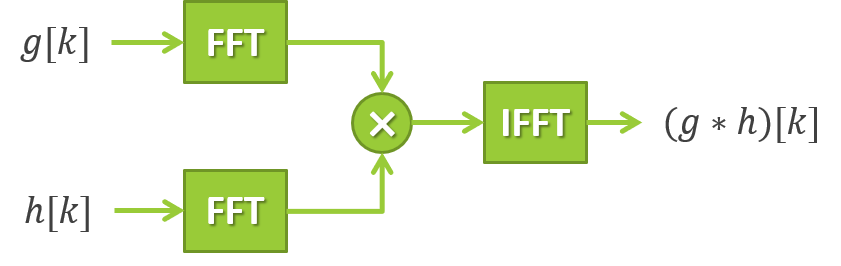

**a)** As entradas `g` e `h` devem possuir o mesmo tamanho. Acrescente zeros à direita de `pulse` e efetue a convolução. Verifique qual é o deslocamento dos pulsos gaussianos em relação às posições esperadas.

% Escreva seu código aqui

% zero padding
pulse_zp = [pulse zeros(1, N-M)];

tic
circConv1 = ifft(fft(rangeLine) .* fft(pulse_zp));
toc
figure
plot(abs(circConv1))
title('Convolução circular')
xlabel('Amostras')
ylabel('Magnitude')

[~,peak_idx_2] = max(abs(linearConv2));
[~,peak_idx_3] = max(abs(linearConv3));


**b)** Use o comando:

para corrigir a variável de entrada que contém o pulso gaussiano, de forma que as posições dos pulsos gaussianos no sinal de saída correspondam às amostras da linha de alcance (exercício 1) referentes aos alvos R1 e R2. Mostre o sinal de saída e o sinal de entrada corrigido.

% Escreva seu código aqui
shift = -floor(M/2);
pulse_zp2 = circshift(pulse_zp, shift);
tic
circConv2 = ifft(fft(rangeLine) .* fft(pulse_zp2));
toc
plot(pulse_zp2)
title('Sinal de entrada')
xlim([0 N])


subplot(2,2,1)
plot(abs(circConv2))
title('Magnitude')

subplot(2,2,3)
plot(rad2deg(angle(circConv2)))
title('Fase (graus)')

subplot(2,2,2)
plot(real(circConv2))
title('Parte real')

subplot(2,2,4)
plot(imag(circConv2))
title('Parte imaginária')




**Exercício 5**

**a)** Na seção "Pulso gaussiano", altere o número de amostras para M = 121 e execute novamente os comandos dos exercícios de 3 e 4. Quais os cuidados devemos tomar para que o pulso seja corretamente posicionado ao final da convolução linear (exercício 3)? E para a convolução circular (exercício 4)?

**b)** Use os comandos

para medir os tempos de execução da convolução linear e da convolução circular. Qual operação é mais rápida?

# **TAREFA**

- Gere os dados brutos do radar conforme a tarefa proposta na Aula Prática 1, incluindo a fase do sinal de retorno para um comprimento de onda de 0,056 m;

- Faça a convolução de cada linha de alcance com o pulso gaussiano abaixo;

- Mostre as vistas superior e de perspectiva para magnitude, fase, parte real e parte imaginária dos dados brutos do radar.

Orientações:

- Escreva o código de tal forma que seja simples substituir o pulso gaussiano pelo pulso do radar, que será visto nas próximas aulas; 

- Este ainda se trata de um resultado parcial. A entrega do simulador SAR será cobrada quando todas as etapas forem concluídas.

- Escreva o código em um arquivo *.m separado;

- Escolha nomes significativos para as variáveis, de acordo com suas funcionalidades;

- Use comentários para facilitar a compreensão do código, especialmente se você utilizar soluções diferentes das apresentadas em aula.